# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.11 在大圆当中生成若干个小圆

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

原问题：[https://www.zhihu.com/question/583360611](https://www.zhihu.com/question/583360611)

# 请问如何使用MATLAB在极坐标内画函数图形的阴影呢？比如这个例4，怎么在这个封闭图形内填充阴影呢？

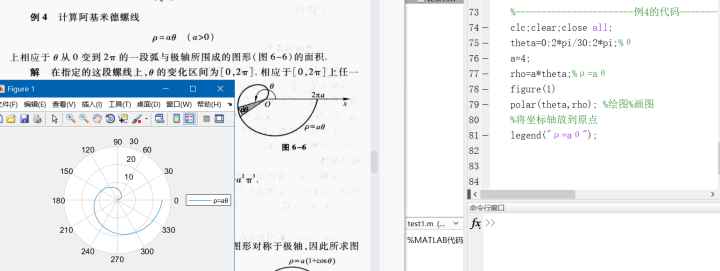

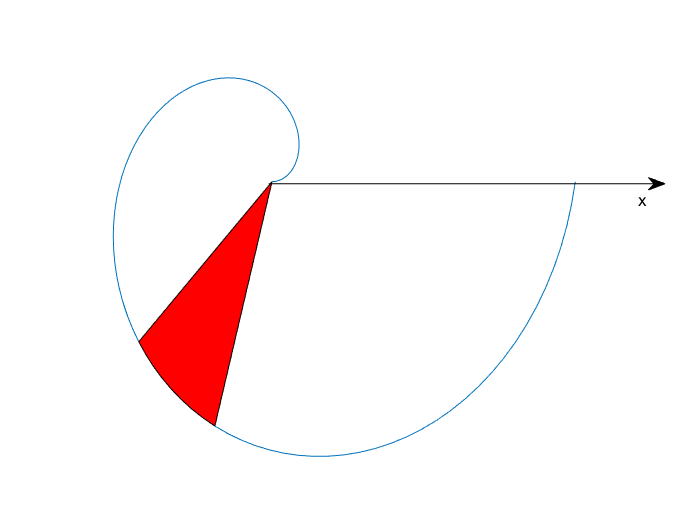

clear; clc;
t = linspace(0, 2*pi, 100);
a = 4;
r = a*t;
x = r .* cos(t);
y = r .* sin(t);
plot(x, y)
t0 = 5/4*pi;
t1 = t0 + pi/6;
idx = t >= t0 & t <= t1;
xx = x(idx);
yy = y(idx);
hold on
% 填充
fill([0, xx], [0, yy], 'r');
hold off
% x 轴
% 具体位置细调，有方法，不细说了
annotation(gcf, 'arrow', [0.384 0.95], [0.65 0.65]);
annotation(gcf, 'textbox',[0.9 0.65 0 0], 'String', 'x', 'EdgeColor', 'none');
axis off